clear;
close all;

reference_motor = 0.3;
max_freq = 400;

%% Read test data
% filename = '..\Test3\00000592.csv';
filename = '..\Test3\00000632.csv';
% filename = 'Test8\00000271.csv';
test_data = csvread(filename, 2, 0);
refer_idx = find(test_data(:, 14) >= reference_motor, 1);
reference_time = test_data(refer_idx, 1); % test_data(1, 1)
test_data(:, 1) = test_data(:, 1)-reference_time; % reset start time
%trim data (remove unnecessary parts)
    isp = refer_idx; %+ 3 * max_freq;
    iep = find(test_data(:, 14) >= reference_motor,1,'last') - 2 * max_freq;
%     isp = refer_idx + 4 * max_freq;
%     iep = refer_idx + 14 * max_freq;
    test_data = test_data(isp:iep, :);

NX = 12;    
NY = 12;
NU = 4;
raw_timestamps = test_data(:,1) * 1e-6;    %(s)    time vector
time_us = test_data(:,1);
raw_states = test_data(:,2:13);            % array of state vector: 12 states
raw_motors = (((test_data(:,14:17)*1000)+1000)-1100)/900;   %SITL: (((0.5595*1000)+1000)-1100)/900=0.51
N = size(test_data,1);                 % size of samples
% %========== to ENU ==============
% % x <-> y, vx <-> vy
% temp = raw_states(:,1); 
% raw_states(:,1) = raw_states(:,2);
% raw_states(:,2) = temp;
% temp = raw_states(:,7); 
% raw_states(:,7) = raw_states(:,8);
% raw_states(:,8) = temp;
% % z <-> -z, vz <-> -vz
% raw_states(:,3) = -raw_states(:,3);
% raw_states(:,9) = -raw_states(:,9);
% % pitch <-> -pitch yaw = (-yaw + pi/2)
% raw_states(:,5) = -raw_states(:,5);
% raw_states(:,6) = mod(-raw_states(:,6)+pi/2, 2*pi);
% % q <-> -q r <-> -r
% raw_states(:,11) = -raw_states(:,11);
% raw_states(:,12) = -raw_states(:,12);
% %================================

timestamps = raw_timestamps';
states = raw_states';
motors = raw_motors';


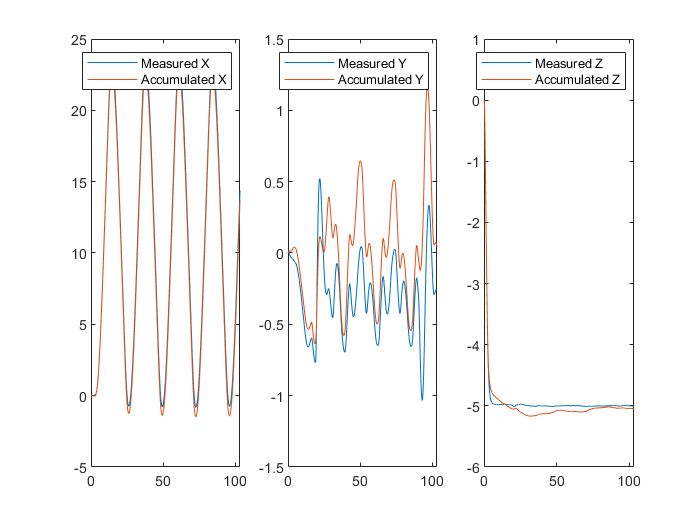

pos_xyz_measuring = states(1:3, :);
pos_xyz_measuring = pos_xyz_measuring - pos_xyz_measuring(:,1);
sub_sample = 1;
v_xyz_measuring = states(7:9, 1:sub_sample:end);
dt = 1/max_freq * sub_sample;
pos_xyz_accu = cumsum(v_xyz_measuring')' * dt;
pos_xyz_accu_time = timestamps(1:sub_sample:end);
figure;
title_names = {'Measured X','Measured Y', 'Measured Z', 'Accumulated X', 'Accumulated Y', 'Accumulated Z' };
for i=1:3
    subplot(1,3,i);
    plot(timestamps, pos_xyz_measuring(i, :));
    hold on;
%     title(title_names{i});
end

for i = 1:3
    subplot(1,3,i);
    plot(pos_xyz_accu_time, pos_xyz_accu(i, :));
%     title(title_names{i+3});
    legend({title_names{i}, title_names{i+3}});
%     ylim([-5, 25]);
end


% save(['GPS_accu_rst' filename(end-6:end) '.mat'], 'pos_xyz_accu_time', 'pos_xyz_accu');

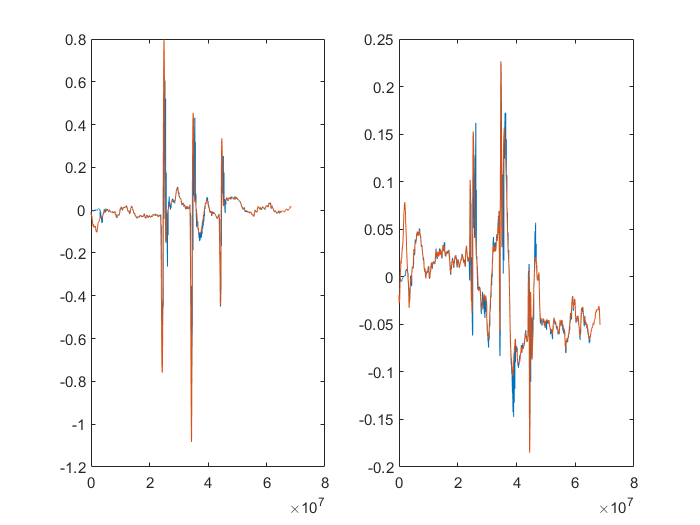

clear;

reference_motor = 0.3;
max_freq = 100;

%% Read test data
filename = '..\Test5\159.csv';
test_data = csvread(filename, 2, 0);
refer_idx = find(test_data(:, 14) >= reference_motor, 1);
reference_time = test_data(refer_idx, 1); % test_data(1, 1)
test_data(:, 1) = test_data(:, 1)-reference_time; % reset start time
%trim data (remove unnecessary parts)
    isp = refer_idx; %+ 3 * max_freq;
    iep = find(test_data(:, 14) >= reference_motor,1,'last') - 2 * max_freq;
%     isp = refer_idx + 4 * max_freq;
%     iep = refer_idx + 14 * max_freq;
    test_data = test_data(isp:iep, :);


sim_states = csvread('..\Test5_rerun\3_SimData_0.2.csv', 0, 0);

sim_att = sim_states(:, 5:7);
sim_t = sim_states(:, 1);
raw_att = test_data(:, 5:7);
raw_t = test_data(:, 1);
figure;
for i=1:2
    subplot(1,2,i);
    plot(sim_t, sim_att(:, i));
    hold on;
end

for i=1:2
    subplot(1,2,i);
    plot(raw_t, raw_att(:, i));
end

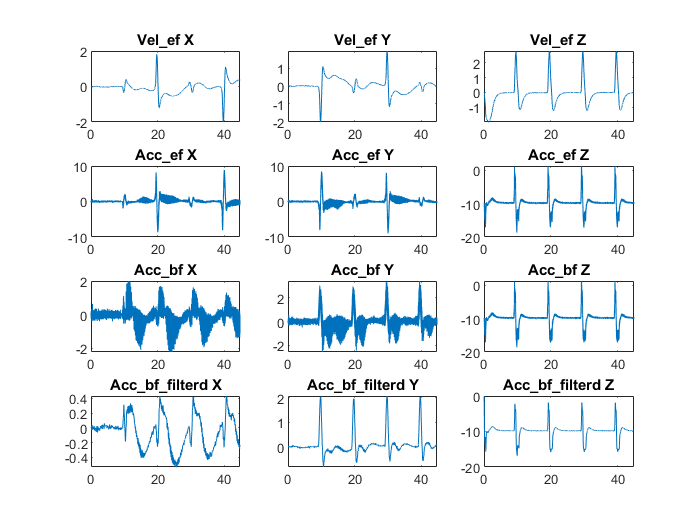

clear;

reference_motor = 0.3;
max_freq = 100;

% Read test data
% filename = 'Test5\159.csv'; %split second attack
% filename = 'Test5\190.csv'; %normal mission
filename = '..\Test5_rerun\00000453.csv';max_freq = 400; % simulation split-second atk


test_data = csvread(filename, 2, 0);
refer_idx = find(test_data(:, 14) >= reference_motor, 1);
reference_time = test_data(refer_idx, 1); % test_data(1, 1)
test_data(:, 1) = test_data(:, 1)-reference_time; % reset start time
%trim data (remove unnecessary parts)
    isp = refer_idx; %+ 3 * max_freq;
    iep = find(test_data(:, 14) >= reference_motor,1,'last') - 2 * max_freq;
%     isp = refer_idx + 4 * max_freq;
%     iep = refer_idx + 14 * max_freq;
    test_data = test_data(isp:iep, :);


time_s = test_data(:, 1) * 1e-6;
vel_ef = test_data(:, 8:10);
accel_ef = diff(vel_ef) ./ diff(time_s);
accel_ef(:, 3) = accel_ef(:, 3) - 9.8;
time_accel = time_s(1:end-1);

title_names = {'Vel\_ef X', 'Vel\_ef Y','Vel\_ef Z','Acc\_ef X','Acc\_ef Y','Acc\_ef Z',...
    'Acc\_bf X','Acc\_bf Y','Acc\_bf Z', 'Acc\_bf\_filterd X','Acc\_bf\_filterd Y','Acc\_bf\_filterd Z'};
figure;
for i=1:3
    subplot(4,3,i);
    plot(time_s, vel_ef(:, i));
    title(title_names{i});
end


for i=1:3
    subplot(4,3,i+3);
    plot(time_accel, accel_ef(:, i));
    title(title_names{i+3});
end

euler_ang = test_data(1:end-1, 5:7);
dcm_ef2bf = angle2dcm(euler_ang(:, 3), euler_ang(:, 2), euler_ang(:, 1), 'ZYX');
accel_bf = zeros(size(accel_ef));
for i = 1:size(accel_ef, 1)
    accel_bf(i, :) = (dcm_ef2bf(:, :, i) * accel_ef(i, :)')';
end

% dt = 1/100;
% vel_bf = cumsum(accel_bf) * dt;

for i=1:3
    subplot(4,3,i+6);
    plot(time_accel, accel_bf(:, i));
    title(title_names{i+6});
end

fc = 5; %cut freq
fs = max_freq;

[b,a] = butter(4,fc/(fs/2));
accel_bf_filterd = filter(b,a,accel_bf);

for i=1:3
    subplot(4,3,i+9);
    plot(time_accel, accel_bf_filterd(:, i));
    title(title_names{i+9});
end

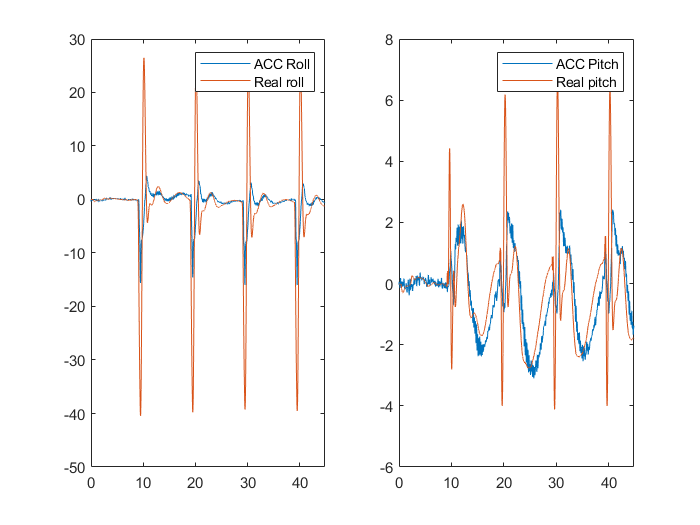


offset = 0;

mu = 0.01;
Gx = accel_bf_filterd(1+offset:end, 1);
Gy = accel_bf_filterd(1+offset:end, 2);
Gz = accel_bf_filterd(1:end-offset, 3);
[roll, pitch] = getRollPitchfromAccUp(Gx, Gy, Gz, mu);
att_acc = [rad2deg(roll), rad2deg(pitch)];
att_acc_time = time_accel(1+offset:end);

figure;
title_name2 = {'ACC Roll', 'ACC Pitch','Real roll', 'Real pitch', 'RawAcc roll', 'RawAcc pitch'};
for i=1:2
    subplot(1,2,i);
    plot(att_acc_time, att_acc(:, i));
    hold on;
    
end

att_real = rad2deg(test_data(:, 5:7)); 
for i=1:2
    subplot(1,2,i);
    plot(time_s, att_real(:, i));
    legend({title_name2{i}, title_name2{i+2}});
end

%continue with real raw acc
raw_acc_filename = '..\Test5_rerun\00000453_acc.csv';
raw_acc_data = csvread(raw_acc_filename, 2, 0);
raw_acc_data(:,1) = raw_acc_data(:, 1) - reference_time;
raw_acc_time = raw_acc_data(:, 1) * 1e-6;
raw_acc_bf = raw_acc_data(:, 2:4);

fc = 5; %cut freq
fs = 25;
[b,a] = butter(1,fc/(fs/2));
raw_acc_bf_filterd = filter(b,a,raw_acc_bf);

% raw_acc_bf_filterd = raw_acc_bf_filterd ./ vecnorm(raw_acc_bf_filterd, 2, 2);

Gx = raw_acc_bf_filterd(:, 1);
Gy = raw_acc_bf_filterd(:, 2);
Gz = raw_acc_bf_filterd(:, 3);
[raw_acc_roll, raw_acc_pitch] = getRollPitchfromAccUp(Gx, Gy, Gz, mu);

Output argument "bnds" (and maybe others) not assigned during call to "mu".


att_raw_acc = rad2deg([raw_acc_roll, raw_acc_pitch]);
for i=1:2
    subplot(1,2,i);
    plot(raw_acc_time, att_raw_acc(:, i));
    legend({title_name2{i}, title_name2{i+2}, title_name2{i+4}});
end

title_names3 = {'raw acc X', 'raw acc Y', 'raw acc Z',...
    'filted raw acc X', 'filted raw acc Y', 'filted raw acc Z'};
figure;
for i=1:3
    subplot(2,3,i);
    plot(raw_acc_time, raw_acc_bf(:, i));
    title(title_names3{i});
end

for i=1:3
    subplot(2,3,i+3);
    plot(raw_acc_time, raw_acc_bf_filterd(:, i));
    title(title_names3{i+3});
end

save('gyro_atk_att_from_acc.mat', 'raw_acc_time', 'att_raw_acc');


% Accelerometer spoof detection (by using gps signal)


function [roll, pitch] = getRollPitchfromAccUp(Gx, Gy, Gz, mu)
%     roll = atan2(-Gy, sqrt(Gz.*Gz + Gx.*Gx));
%     roll = atan2(-Gy, -sign(Gz).* sqrt(Gz.*Gz + Gx.*Gx*mu));
    roll = atan2(-Gy, -Gz);
    pitch = atan2(Gx, sqrt(Gy.*Gy + Gz.*Gz));
end

function [roll, pitch] = getRollPitchfromAccDown(Gx, Gy, Gz, mu)
%     roll = atan2(Gy, sqrt(Gz.*Gz + Gx.*Gx));
    roll = atan2(Gy, sign(Gz).* sqrt(Gz.*Gz + Gx.*Gx*mu));
    pitch = atan2(-Gx, sqrt(Gy.*Gy + Gz.*Gz));
end